clear;

%=======Задающий сигнал======
G_g = [0 2 0;
    -2 0 0;
    0 0 0];
Y_g = [1 0 -2];
w_g0 = [1; 0; 1];

%======Система==========

A = [5 8 5; -6 -9 -8; 6 6 5];
B = [2; 0; 0];
C = [2 -3 -2];
Bf = [-3 1; 3 0; 0 0];
D = [7];
Df = [5 6];
x0 = [0; 0; 0];
%=====Внешнее возмущение====
G_f = [0 1 0 1;
    -26 -7 20 -11;
    0 1 -1 2;
    16 4 -14 8];
Y_f = [2 0 -2 1;
    -4 -2 4 -3];
w_f0 = [1; 1; 1; 1];
wfx_0 = [1; 1; 1; 1; 0; 0; 0];

%====Синтез К========
K = [-6.5 -0.25 0.25];

%====Синтез Кg========
Kg = [0.0468 0.2563 -0.3738];

%====Синтез Кf========
Kf = [16.0012 6.4817 -11.3156 6.2353];


Q = [0.2000 -0.4000 -2.0000;    0.2500 -0.2500 -1.0000;    0.2400 -0.3200 -1.3333];
%iQ = pinv(Q)

Q1 = [0.2000 -0.4000 -2.0000 0;
    0.2500 -0.2500 -1.0000 0;
    0.2400 -0.3200 -1.3333 0; 0 0 0 0];
iQ = pinv(Q)

iQ =     2.4977   19.9963  -18.7441
   17.4930   39.9888  -56.2324
   -3.7488   -5.9981    9.3721


%=============================
Yf2 = [1; 1; 1; 1]

Yf2 =      1
     1
     1
     1


Gf2 = [-1 0 0 0; 0 -1.5 0 0; 0 0 -2 0; 0 0 0 -5]

Gf2 =    -1.0000         0         0         0
         0   -1.5000         0         0
         0         0   -2.0000         0
         0         0         0   -5.0000


C_b = [0 0.3333 0; 1.0000 1.0000 0];


cvx_begin sdp

variable Q_f(4, 4)

Q_f*G_f - Gf2*Q_f == Yf2*Df*Y_f;
cvx_end

Homogeneous problem detected; solution determined analytically.
Status: Solved
Optimal value (cvx_optval): +0
 



Q_f

Q_f =   -59.6000  -19.6000   46.0000  -29.0000
  -43.0400  -15.0892   33.4892  -21.3600
  -30.9000  -11.5000   24.2000  -15.7000
   -7.6233   -3.6976    6.2334   -4.5013


det(Q_f)

ans = 0.5420

iQf = pinv(Q_f)

iQf =    -4.8133   18.4573  -17.9174    5.9187
   -0.2004    5.0107   -7.4924    3.6461
   -8.3254   29.5147  -26.7517    6.8875
   -3.2127    5.4970   -0.5464   -3.7033


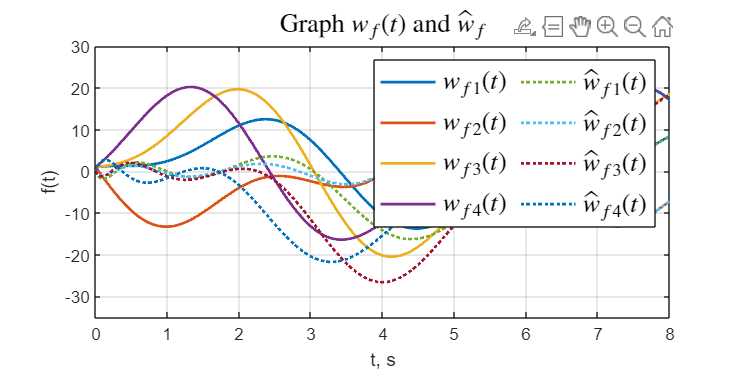



G = [-1 0 0; 0 -2 0; 0 0 -1.5];
Y = [1; 1; 1];

%=======Modeling=====
open_system('task_32_sim');
set_param('task_32_sim/x', 'VariableName', 'x')
set_param('task_32_sim/y', 'VariableName', 'y')
set_param('task_32_sim/u', 'VariableName', 'u')
set_param('task_32_sim/e', 'VariableName', 'e')
set_param('task_32_sim/ef', 'VariableName', 'ef')
set_param('task_32_sim/wf', 'VariableName', 'wf')
set_param('task_32_sim/wf_', 'VariableName', 'wf_')



out = sim('task_32_sim');
figure('Position', [100 100 800 400])

plot(out.wf,'-', 'LineWidth',1.5);
hold on
plot(out.wf_,':', 'LineWidth',1.5);

grid()
title('Graph $w_f(t)$ and $\hat{w}_f$','Interpreter','latex',  'FontSize', 14)
%legend('$e_{f1}(t)$', '$e_{f2}(t)$', '$e_{f3}(t)$', '$e_{f4}(t)$', 'Interpreter','latex',  'FontSize', 14, 'NumColumns', 2)
legend('$w_{f1}(t)$', '$w_{f2}(t)$', '$w_{f3}(t)$', '$w_{f4}(t)$', ...
    '$\hat{w}_{f1}(t)$', '$\hat{w}_{f2}(t)$', '$\hat{w}_{f3}(t)$','$\hat{w}_{f4}(t)$','Interpreter','latex',  'FontSize', 14, 'NumColumns', 2)
ylabel('f(t)')
xlabel('t, s')
ylim([-35 30])
hold off